**Question 1**

% SETUP - DO NOT EDIT
n = -10:10;

% ANSWER

x1 = zeros(1,length(n));
impulse = n == 5; 
    for i=1:length(n)
        x1(i) = impulse(i);
    end                     %REPLACE WITH YOUR ANSWER%
x2 = zeros(1,length(n)); 
    for i = 1:length(n)
        unitstep = n >= 3; 
        x2(i) = (0.9 ^ (n(i) -3)) * unitstep(i);
    end                     %REPLACE WITH YOUR ANSWER%
x3 = zeros(1,length(n)); 
    for i=1:length(n)
        if n(i) >= -3 && n(i) < 3
            x3(i) = 2 * cos(0.1 * pi * n(i));
        end
    end                     %REPLACE WITH YOUR ANSWER%

% PLOTTING - DO NOT EDIT 
disp('Question 1 Figures')

Question 1 Figures


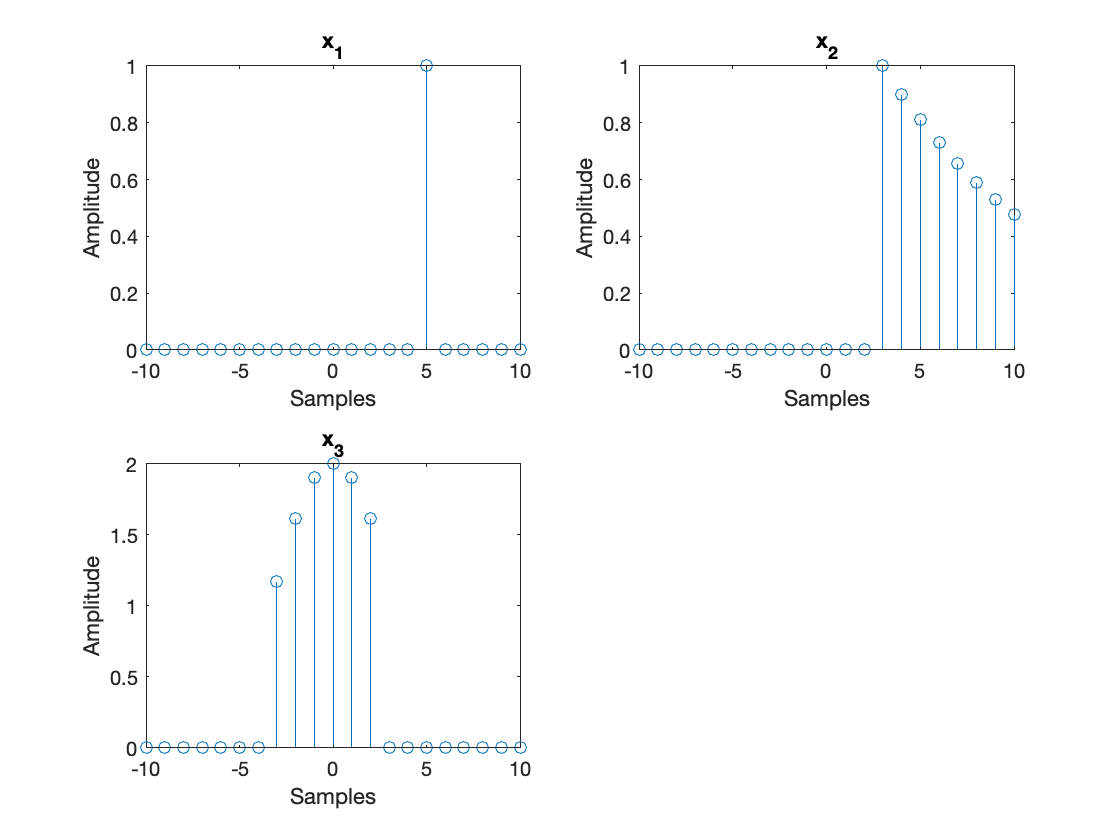

figure; 
subplot(2,2,1); stem(n, x1); title('x_1');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,2,2); stem(n, x2); title('x_2');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,2,3); stem(n, x3); title('x_3');
xlabel('Samples'); ylabel('Amplitude');

**Question 2**

% PRE-DEFINED INPUT SIGNAL - DO NOT EDIT 
n = -10:20;
x_test = n.*(n > -3).*(n < 4);

% FUNCTIONS - DO NOT EDIT 
y1 = delay(x_test,2);
y2 = distort(x_test,10);
y3 = reverb(x_test,6,0.5);

% PLOTTING - DO NOT EDIT
disp('Question 2 Figures')

Question 2 Figures


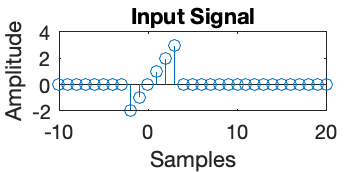

figure; 
set(gcf, 'Units', 'Inches', 'Position',[0 0 2.5 1.2])
stem(n, x_test); title('Input Signal')
xlabel('Samples'); ylabel('Amplitude');

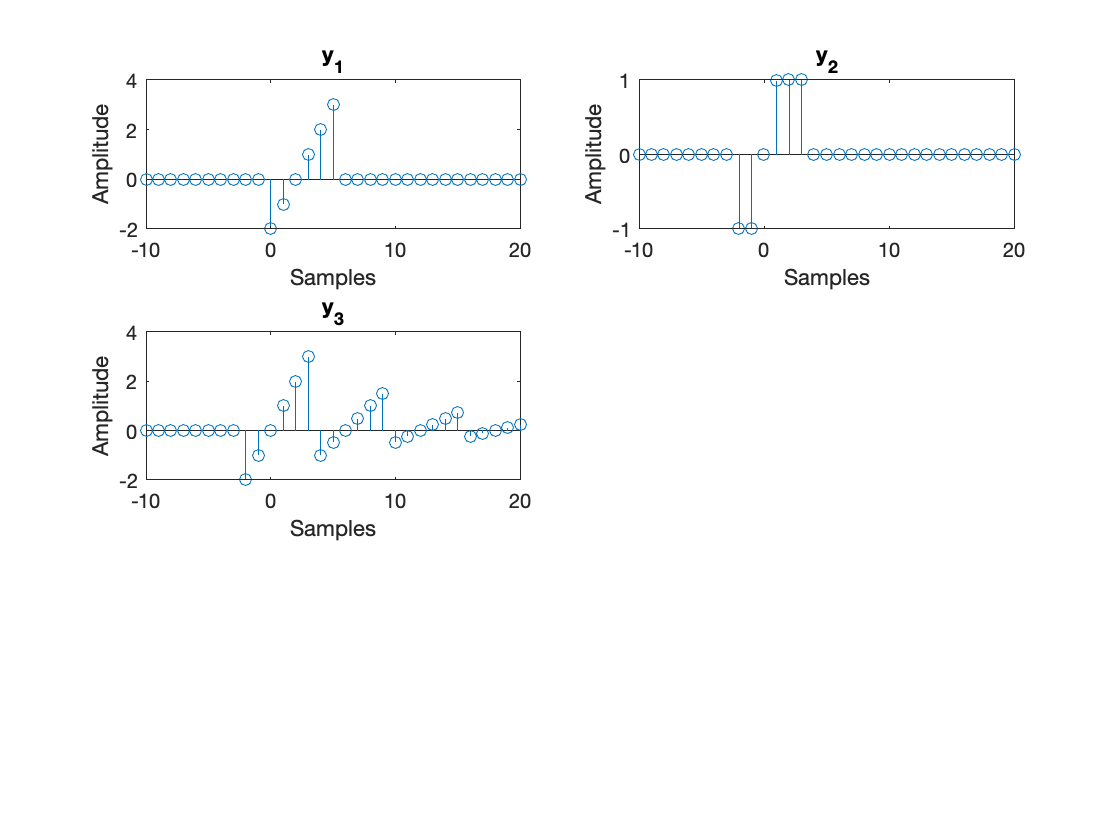


figure; 
subplot(3,2,1); stem(n, y1); title('y_1');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,2); stem(n, y2); title('y_2');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,3); stem(n, y3); title('y_3');
xlabel('Samples'); ylabel('Amplitude');


% LOAD SECOND TEST INPUT - DO NOT EDIT 
[x_test2, Fs] = audioread('rolemusic.wav');

% FUNCTIONS - DO NOT EDIT 
z1 = delay(x_test2,200);
z2 = distort(x_test2,100);
z3 = reverb(x_test2,5000,0.6);

% PLAY SOUNDS
% UNCOMMENT TO LISTEN TO AUDIO!
%soundsc(z1, Fs); pause(length(z1)/Fs);
%soundsc(z2, Fs); pause(length(z2)/Fs);
%soundsc(z3, Fs); pause(length(z3)/Fs);

**Functions**

function y=delay(x,M)
    %Ensure input is what it should be
    if mod(M,1)~=0; error('M must be a integer.'); end
    
    %REPLACE WITH YOUR ANSWER%
    
     y = zeros(1,length(x));
     for i = 1:1:length(x)                 
         if i <= M
             y(i) = 0;
         else
             y(i) = x(i-M);
         end
     end
      
end

function y=distort(x,a)
    
    %REPLACE WITH YOUR ANSWER%
    y = zeros(1,length(x));
    for i = 1:length(x)
        if x(i) < 0 
            y(i) = -1 * (1 - exp(-a * abs(x(i))));
        elseif x(i) == 0 
            y(i) = 0;
        elseif x(i) > 0
            y(i) = (1- exp(-a * abs(x(i))));
        end
    end
    
end

function y=recur_avg(x,a)
    
    y=zeros(length(x),1);
    
end

function y=reverb(x,M,A)
    %Ensure input is what it should be
    if mod(M,1)~=0; error('M must be a integer.'); end
    if M<=0; error('M must be a positive integer.'); end
    y = zeros(1,length(x));
    for i = 1:length(x)
        if i <= M
           y(i) = x(i);
        else
           y(i) = A * y(i-M) + x(i);      
        end
    end
    
    
end